imfinfo('C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\MAFood121\images\com_tam\3_1.jpg')

ans = struct with fields:
           Filename: 'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\MAFood121\images\com_tam\3_1.jpg'
        FileModDate: '03-Nov-2017 19:39:05'
           FileSize: 33461
             Format: 'jpg'
      FormatVersion: ''
              Width: 512
             Height: 308
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}


og_imds = imageDatastore('C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\MAFood121\images', ...
    'FileExtensions', {'.jpg'}, ...
    'IncludeSubfolders',true, ...
    'LabelSource',"foldernames", "ReadFcn", @scaleimage)

og_imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\datasets\MAFood121\images\artichoke_bottoms_in_olive_oil\1.jpg';
                              ' ...\datasets\MAFood121\images\artichoke_bottoms_in_olive_oil\100.jpg';
                              ' ...\datasets\MAFood121\images\artichoke_bottoms_in_olive_oil\102.jpg'
                               ... and 29249 more
                              }
                     Folders: {
                              ' ...\Project 1 - Thai Food Image Recognition\datasets\MAFood121\images'
                              }
                      Labels: [artichoke_bottoms_in_olive_oil; artichoke_bottoms_in_olive_oil; artichoke_bottoms_in_olive_oil ... and 29249 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg

sizeInput = [224 224 3]

sizeInput =    224   224     3



imds = augmentedImageDatastore(sizeInput, og_imds, "OutputSizeMode", "centercrop")

imds =   augmentedImageDatastore with properties:

             NumObservations: 29252
                       Files: {29252×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'centercrop'
        DispatchInBackground: 0


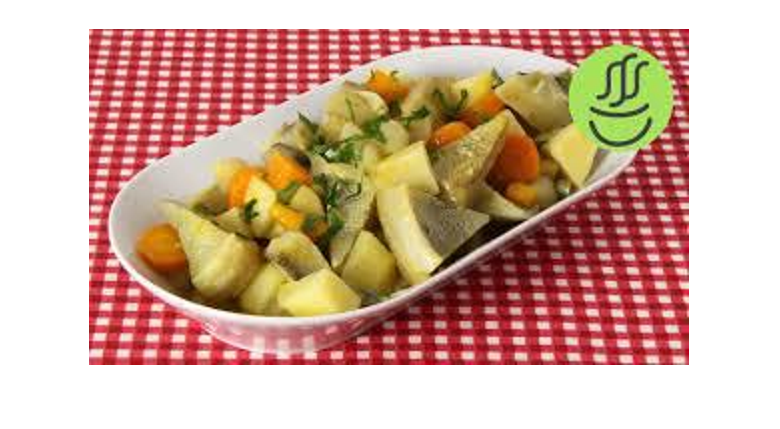


imshow(preview(og_imds))

figure;

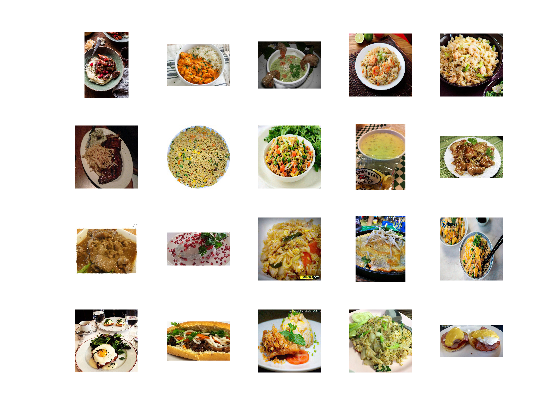


perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(og_imds)

labelCount = 136×2 table
                    Label                    Count
    _____________________________________    _____

    artichoke_bottoms_in_olive_oil            250 
    baby_back_ribs                            250 
    banh_mi                                   110 
    banh_xeo                                  120 
    barbecued_red_pork_in_sauce_with_rice     478 
    beef_bourguignon                          119 
    beef_carpaccio                            250 
    beef_in_oyster_sauce                      107 
    biryani                                   125 
    blanquette_de_veau                        120 
    borek                                     250 
    breakfast_burrito                         250 
    bruschetta                                250 
    bun_cha                                   100 
    butter_chicken                            115 
    caesar_salad                       

img = readimage(og_imds,1);
size(img)

ans =    336   600     3



numTrainFiles = 750;
% [imdsTrain,imdsValidation] = splitEachLabel(imds,0.8,'randomize');
shuffle(imds)

ans =   augmentedImageDatastore with properties:

             NumObservations: 29252
                       Files: {29252×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'centercrop'
        DispatchInBackground: 0



totalDatasetSize = size(imds.Files, 1)

totalDatasetSize = 29252

trainingSize = ceil(totalDatasetSize * 0.8);
testingSize = totalDatasetSize - trainingSize;

imdsTrain = partitionByIndex(imds,[1:trainingSize]);
imdsValidation = partitionByIndex(imds,[testingSize:totalDatasetSize]);



% layers = [
%     imageInputLayer(sizeInput, 'Name','input')
%     % crop2dLayer('centercrop','Name','crop')
%     
%     convolution2dLayer(3,8,'Padding','same', 'Name','c2d1')
%     batchNormalizationLayer('Name','BN_1')
%     reluLayer('Name','relu_1')
%     
%     maxPooling2dLayer(2,'Stride',2, 'Name','pooling1')
%     
%     
%     convolution2dLayer(3,16,'Padding','same', 'Name','c2d2')
%     batchNormalizationLayer('Name','BN_2')
%     reluLayer('Name','relu_2')
%     
%     maxPooling2dLayer(2,'Stride',2, 'Name','pooling2')
%     
%     
%     convolution2dLayer(3,16,'Padding','same', 'Name','c2d3')
%     batchNormalizationLayer('Name','BN_3')
%     reluLayer('Name','relu_3')
%     
%     maxPooling2dLayer(2,'Stride',2, 'Name','pooling4')
%     
%     
%     convolution2dLayer(3,16,'Padding','same', 'Name','c2d4')
%     batchNormalizationLayer('Name','BN_4')
%     reluLayer('Name','relu_4')
%     
%     maxPooling2dLayer(2,'Stride',2, 'Name','pooling5')
%     
%     
%     convolution2dLayer(3,16,'Padding','same', 'Name','c2d5')
%     batchNormalizationLayer('Name','BN_5')
%     reluLayer('Name','relu_5')
%     
%     maxPooling2dLayer(2,'Stride',2, 'Name','pooling6')
%     
%     
%     convolution2dLayer(3,16,'Padding','same', 'Name','c2d6')
%     batchNormalizationLayer('Name','BN_6')
%     reluLayer('Name','relu_6')
%     
%     maxPooling2dLayer(2,'Stride',2, 'Name','pooling7')
%     
% 
%     convolution2dLayer(3,16,'Padding','same', 'Name','c2d7')
%     batchNormalizationLayer('Name','BN_7')
%     reluLayer('Name','relu_7')
%     
%     maxPooling2dLayer(2,'Stride',2, 'Name','pooling8')
%     
%     
%     convolution2dLayer(3,32,'Padding','same', 'Name','c2d8')
%     batchNormalizationLayer('Name','BN_8')
%     reluLayer('Name','relu_8')
%     
%     fullyConnectedLayer(500, "Name", "a1")
%     reluLayer('Name','relu_a1')
%     fullyConnectedLayer(500, "Name", "a2")
%     reluLayer('Name','relu_a2')
%     fullyConnectedLayer(500, "Name", "a3")
%     reluLayer('Name','relu_a3')
%     
%     fullyConnectedLayer(500, "Name", "a4")
%     reluLayer('Name','relu_a4')
%     fullyConnectedLayer(500, "Name", "a5")
%     reluLayer('Name','relu_a5')
%     fullyConnectedLayer(500, "Name", "a6")
%     reluLayer('Name','relu_a6')
%     
%     fullyConnectedLayer(500, "Name", "a7")
%     reluLayer('Name','relu_a7')
%     fullyConnectedLayer(500, "Name", "a8")
%     reluLayer('Name','relu_a8')
%     fullyConnectedLayer(136, "Name", "a9")
%     reluLayer('Name','relu_a9')
%     
%     softmaxLayer('Name','sftmax1')
%     classificationLayer('Name','classifier')];

lgraph = resnet50()

lgraph =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}


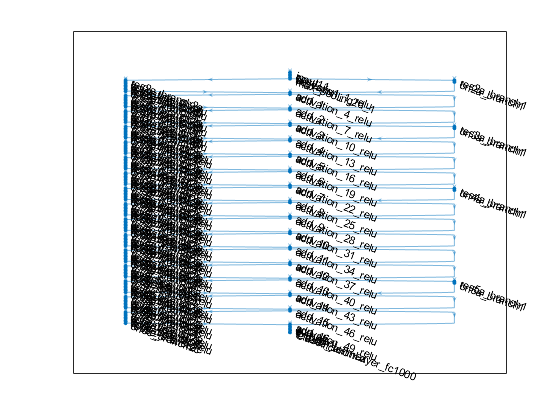

% lgraph = layerGraph(lgraph)
figure
plot(lgraph)



options = trainingOptions('adam', ...
    'InitialLearnRate',3e-5, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'ExecutionEnvironment','multi-gpu', ...
    'ValidationData',imdsValidation, ...
    'Verbose',false, ...
    'MiniBatchSize', 64, ...
    'Plots','training-progress');


net = trainNetwork(imdsTrain,lgraph,options);

Error using trainNetwork (line 170)
Layers argument must be an array of layers or a layer graph.

save net